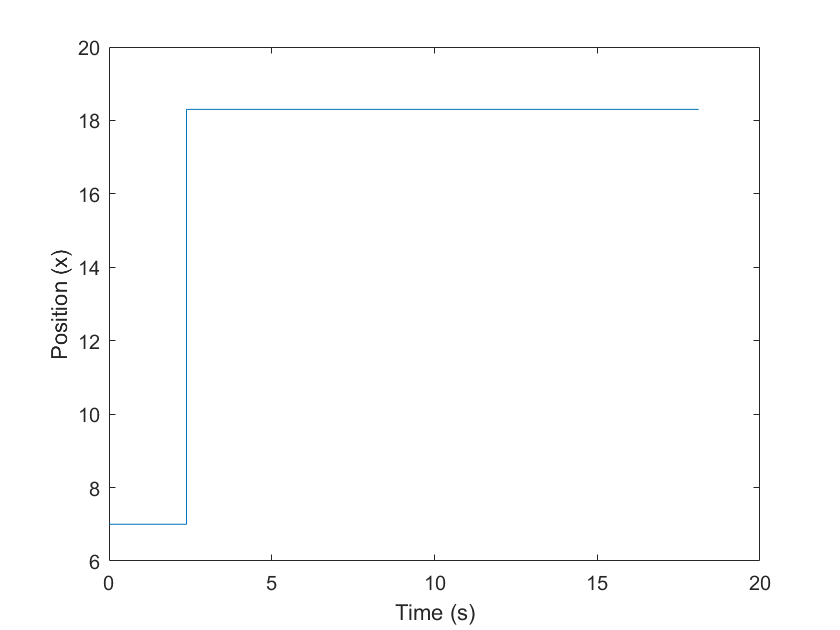

clear, clc;

load('trp46r2.mat');
data = trp46r2;

t_array = data.X.Data;
voltage = data.Y(11).Data; %RMV
summin = data.Y(1).Data; %maybe input r?
input_r = data.Y(2).Data;
summin = data.Y(3).Data; %CV, maybe theta?
summin = data.Y(4).Data; %CVF some step something
summin = data.Y(5).Data; %NF another step thing
summin = data.Y(6).Data; %PC another step thing
summin = data.Y(7).Data; %PPF another step thing
summin = data.Y(8).Data; %PPU somethign useful
summin = data.Y(9).Data; %PV somethign useful
summin = data.Y(10).Data; % another step thing

% Plot response
figure();
plot(t_array, summin)
hold on
%plot(t_array, input_r)
xlabel("Time (s)")
ylabel("Position (x)")

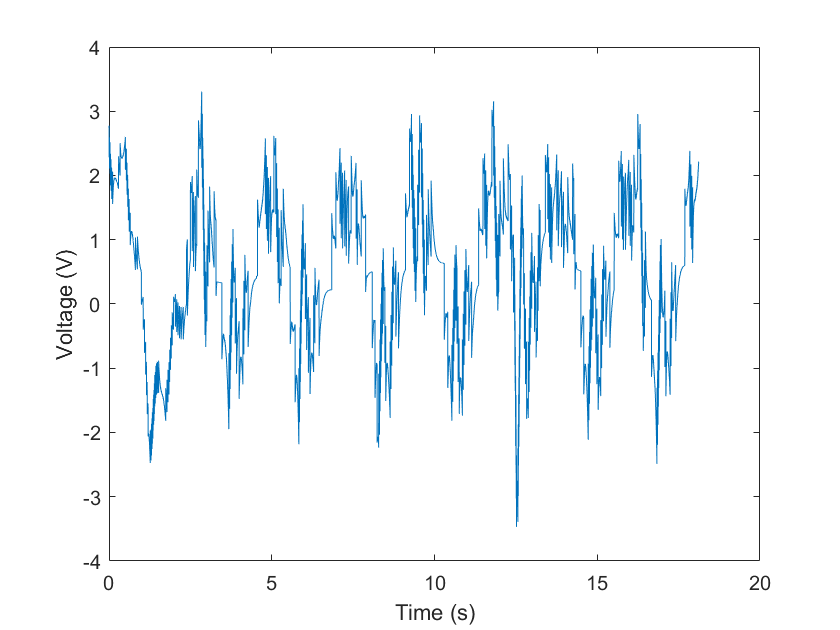

% legend("Cart position", "Input r")
% 
% % Print info
% K = data.K
% N = data.N
% 
% % Plot theta, so we can check small angle approx
% figure();
% plot(data.t, data.theta)
% xlabel("Time (s)")
% ylabel("Angle (rad, maybe deg)")

% Plot Voltage
figure();
plot(t_array, voltage)
xlabel("Time (s)")
ylabel("Voltage (V)")